# LAB 2 guidance

# Pre-lab solution


$$H\left(s\right)=\frac{16}{s^2 +6s+16}=\frac{G\omega_n^2 }{s^2 +2\zeta \omega_n s+\omega_n^2 }$$


1. 

- 
$$\omega_n^2 =16\Longrightarrow \omega_n =4$$


- G = 1

- 
$$\zeta =\frac{3}{4}$$


- 
$$\omega_d =\omega_n \sqrt{1-\zeta }=2\;$$


- 
$$\sigma =\zeta \omega_n =3$$


2. $\omega =0\ldotp 1\;\mathrm{rad}/\mathrm{sec}$


$${H\left(s\right)|}_{s=j\omega } =H\left(j\omega \right)=\frac{16}{{\left(\mathrm{j0}\ldotp 1\right)}^2 +\mathrm{j0}\ldotp 6+16}\doteq 0\ldotp 9986-j0\ldotp 0374\;$$



$$\angle H(j \omega) = -0.0374 \, radians
$$



$$|H\left(j\omega \right)|=0\ldotp 9993$$



$$y_{\mathrm{ss}} \left(t\right)=0\ldotp 9993\;\mathrm{sin}\left(0\ldotp 1t-0\ldotp 0374\right)$$


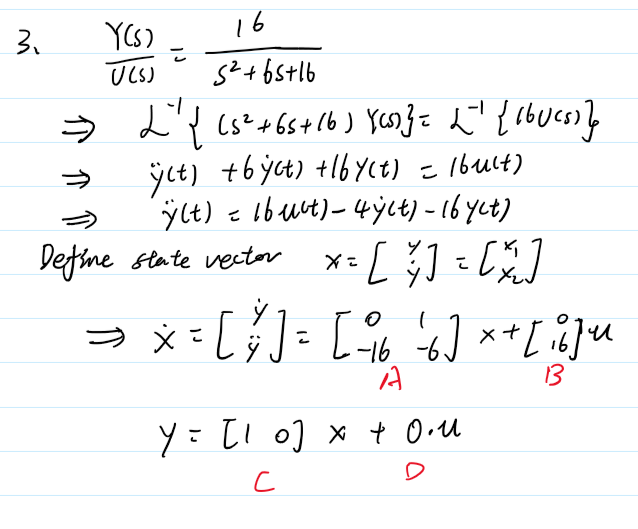

# EXPERIMENTAL PROCEDURE

## 8.1: SIMULATE SYSTEM WITH LSIM

#### PLEASE MAKE SURE YOU HAVE THE CONTROL SYSTEMS TOOLBOX ALREADY INSTALLED!

Here shows an example for using lsim.

Assuming the system is define as (Just an example)


$$\frac{Y}{U}=\frac{5}{s^2 +2s+3}$$


Its matrix format is


$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-3 & -2
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\\
5
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack ,D=0\ldotp$$


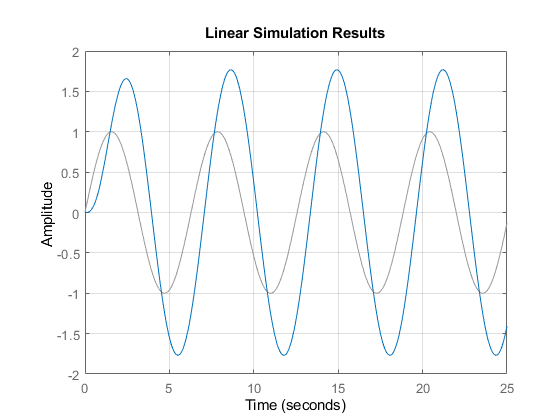

% Define the transfer function of the system
% Please search 'tf' in MATLAB documentation for understanding this function
H = tf(5,[1 2 3]);
% Define A,B,C,D
A = [0,1; -3,-2];
B = [0;5];
C = [1 0];
D = 0;
% Define state-space model. 
% Please search 'ss' in MATLAB documentation for understanding this function
sys = ss(A,B,C,D);
% Define initial state
x0 = [0,0];
% Define the input. Here using sinusoidal signal
% **** Please search 'gensig' in MATLAB documentation for learning how to
% genaerate signal. 'gensig' can also used to create square signal.
% u(t) = sin(t)
tau = 2*pi; % period T = 2*pi/1
% 0:Ts:Tf
Ts = 0.01; % time step
Tf = 25; % Duration **** pick a proper dutation for the system in the lab manual
[u,t] = gensig('sin',tau,Tf,Ts);
% Simulate the system
lsim(sys,u,t, x0);
grid on;

The plot shows the input (u,t) in gray and the system response in blue.

## 8.2:  SIMULATE SYSTEM WITH EULER METHOD

(a) This f.m file is similar to the function 'fld_lvl' defined in the Table 1. But you should give the dx matrix format.

**The f.m define in this guidance refer the example system above, not what in the lab manual**

(b) The procedures are similar to the function 'lab2' defined in the Table 1.

The example shown in Euler.m. The inputs are the initial condition x0 and the step-size h.

Note: 'flops' function has been removed from MATLAB, use tic, toc instead.

(c) 

- **In your lab report. You should run the time steps by h = 1, 0.1, 0.05, 0.01 to show the simulation time.**

- **You don't have to show Table 1 in your lab report. Since you will have your f.m and Euler.m uploaded to MATLAB Drive**

- **You don't have to collect the Table 2 in your lab report, the diffrent elapsed time will be show in this section.**

Euler Simulation Took = 2.39213 ms


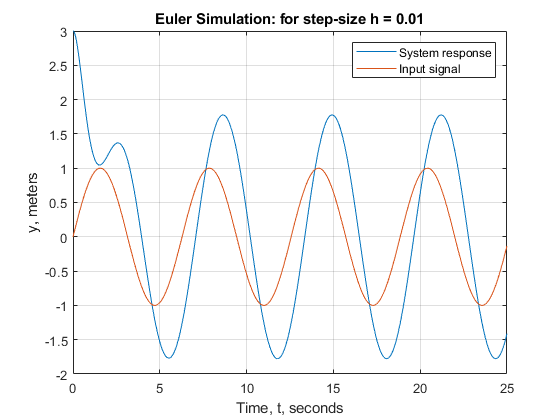

Ts = 0.01; % time step
[u,t] = gensig('sin',tau,Tf,Ts);
% Define initial state
x0 = [3,0];
% Define step-size
h = 0.01;
Euler(t,x0,h,u,1);

Simulation time step for h = 1

Ts = 1; % time step
[u,t] = gensig('sin',tau,Tf,Ts);
h = 1;
Euler(t,x0,h,u,0);

Euler Simulation Took = 0.444679 ms


Simulation time step for h = 0.05

Ts = 0.05; % time step
[u,t] = gensig('sin',tau,Tf,Ts);
h = 0.05;
Euler(t,x0,h,u,0);

Euler Simulation Took = 0.248844 ms


- **In your lab report, you should compute the time that it took to achieve 1% steady-state  (i.e., setting time Ts) with the value predicted by the pole locations. **

## 8.3&8.4: SIMULATE SYSTEM WITH ODE23

(a) 

help ode23

 ode23  Solve non-stiff differential equations, low order method.
    [TOUT,YOUT] = ode23(ODEFUN,TSPAN,Y0) with TSPAN = [T0 TFINAL] integrates 
    the system of differential equations y' = f(t,y) from time T0 to TFINAL 
    with initial conditions Y0. ODEFUN is a function handle. For a scalar T
    and a vector Y, ODEFUN(T,Y) must return a column vector corresponding 
    to f(t,y). Each row in the solution array YOUT corresponds to a time 
    returned in the column vector TOUT.  To obtain solutions at specific 
    times T0,T1,...,TFINAL (all increasing or all decreasing), use TSPAN = 
    [T0 T1 ... TFINAL].     
    
    [TOUT,YOUT] = ode23(ODEFUN,TSPAN,Y0,OPTIONS) solves as above with default
    integration properties replaced by values in OPTIONS, an argument created 
    with the ODESET function. See ODESET for details. Commonly used options
    are scalar relative error tolerance 'RelTol' (1e-3 by default) and vector
    of a

Search 'ode23' in MATLAB Documentation to see the examples given by MATLAB

(b)&(c): In this section, you should create a new function called f_ode23. In this fuction, define the input 'u'

tspan = [0 25]; % Interval of integration
x0 = [3;0]; % Initial condition
% u(t) = sin(t) defined in f_ode23
omg = 1;
tic 
[t_out,y] = ode23(@(t,x) f_ode23(t,x,omg), tspan, x0);
tm = toc; 
tm = tm*1000; 

% figure
% subplot(211)
% plot y versus t
% str = sprintf('ODE23 Simulation Took %g ms for u = sin(t)', tm); 
% hold on
% plot input versus t ([u,t] = gensig('sin',tau,Tf,Ts);)
% title (str)
% xlabel('Time, t, seconds');
% ylabel('$ \bf y$', 'Interpreter', 'latex');
% grid on;
% subplot(212)
% plot y dot versus t
% xlabel('Time, t, seconds');
% ylabel('$ \bf \dot{y}$', 'Interpreter', 'latex');
% grid on;

## 8.5

Choose three diffrent values of $\omega$. Implement (b)&(c) above.

Discuss and compare the amplitude and phase shift of the output relative to the input.

 How do the steady state values compare with those predicted by frequency response (try using the ‘Bode’ function)?  

% bode(H); find the magnitude and phase in frequecy related to the input.
% analyze them.
% Notice that the unit in bode is db and deg
% for comparing them to what we calculate above, convert db to amplitude
% and deg to rad
% db = 20*log10(amp/amp_ref), where amp_ref = 1.